# Section C H2 Optimal Controller

run("quanser_aero_parameters.m");
run("quanser_aero_state_space.m");

Plant = ss(A,B,C,D);
Plant = minreal(Plant);
G = Plant.NominalValue;
s = tf('s');


## **Build weights:**

**Performance weight**

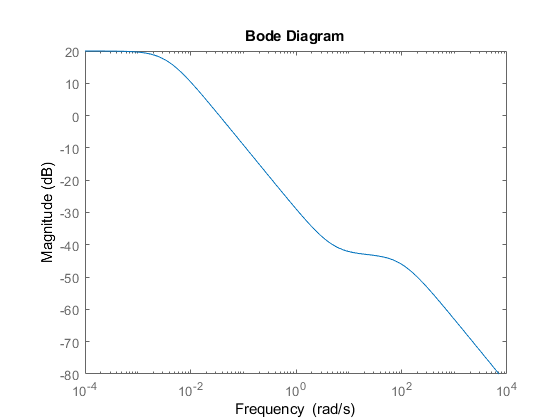

BW = 5; %rad/s
DCGain = 1/1000;
HFGain = sqrt(2);

Wpsingle = 1/makeweight(DCGain,BW,HFGain);
Wpsingle = Wpsingle*(1/(s+100)); %tacking on HF pole so Wp is strictly proper for H2 syn
clf
bodemag(Wpsingle);

Wp = Wpsingle * eye(2);

**Control Weight**


%Wu_Pitch = 0.4*(s+1)/(s+100);
Wu_Pitch=  0.01*(s+10)/(s+400);
Wu_Yaw =  0.01*(s+10)/(s+400);

Wu = [Wu_Pitch 0; 
     0 Wu_Yaw];

Wu = minreal(Wu);
%clf
%bodemag(Wu)

## H2 synthesis

generalized plant derivation: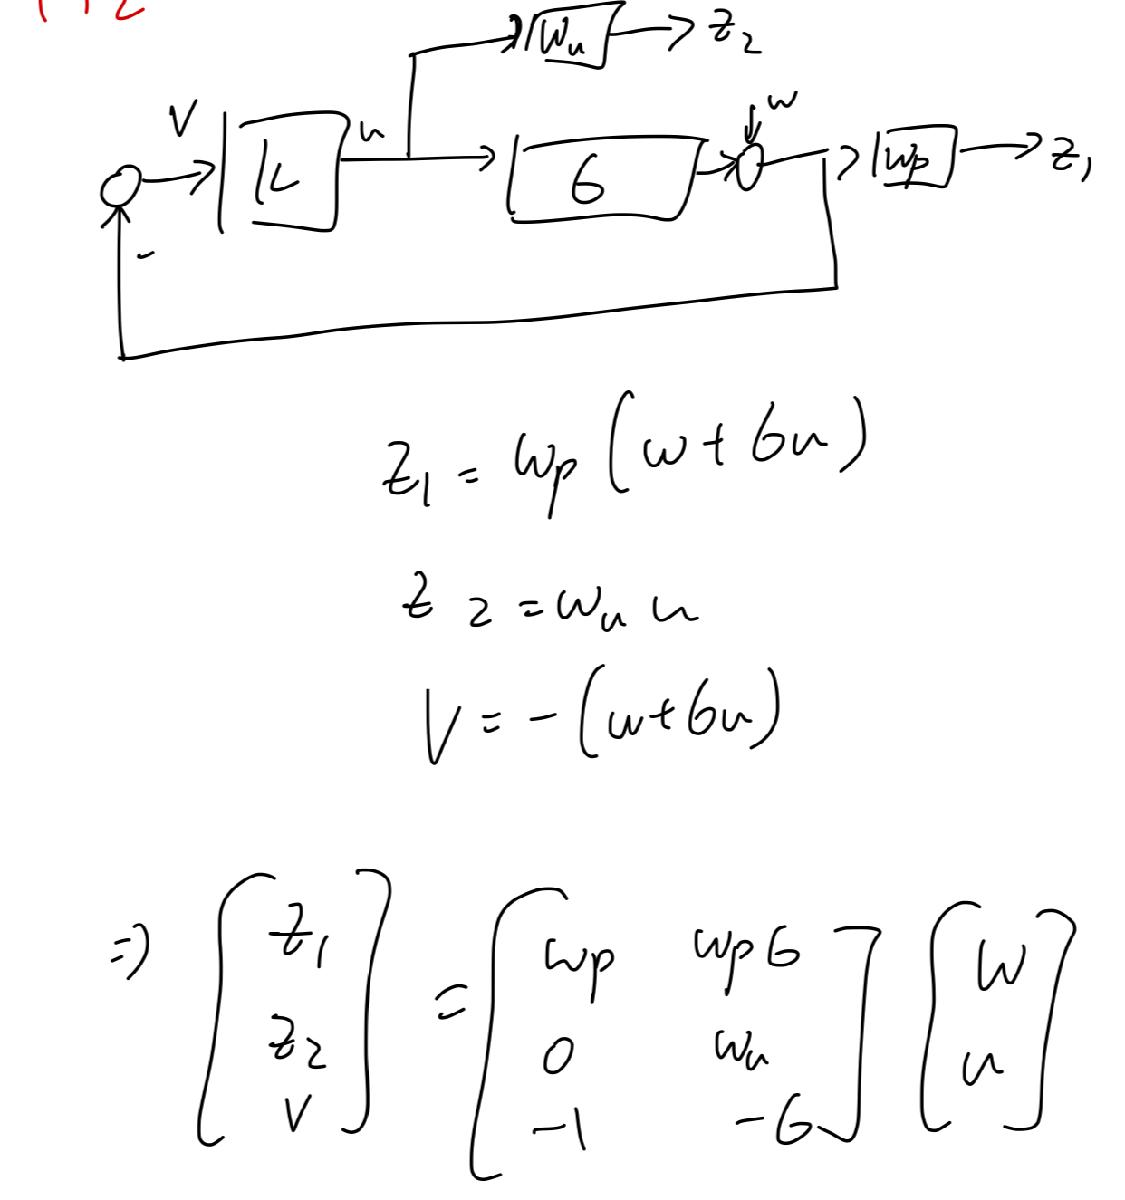

zero = zeros(2,2);
one = eye(2);
Pref = [Wp  Wp*G;
        zero  Wu;
        -one  -G];
Pref = minreal(Pref);

8 states removed.


[Kh2 CL_ref GAMref] = h2syn(Pref,2,2);
GAMref

GAMref = 0.0846

## Simulate

run("SimulinkStartup.mlx");

Error using run (line 66)
SimulinkStartup.mlx not found.

K = Kh2;

out = sim("My_MLC_Aero_Simulink.slx");

PlotSimRes(out,'angles')
PlotSimRes(out,'controls')

PlotSimRes(out,'errors')

## Robust Stability and Robust Performance

Robust Stability

run("UncertaintyFit.mlx");


D_1 = ultidyn('D_1',1);
D_2 = ultidyn('D_2',1);


Delta = [D_1 0;
        0 D_2];
Gunc = G*(eye(2)+W_I*Delta); 


Sunc = inv(eye(2)+Gunc*Kh2);
Tunc = feedback(Gunc*Kh2,eye(2));
[mu, flag] = robmu(Sunc)

$\mu (S) = 0.7361 < 1
$ => system is robustly stable

Robust Performance

Punc = [Wp  Wp*Gunc;
        zero  Wu;
        -one  -Gunc];

N = lft(Punc,Kh2);
[M,Delta] = lftdata(N);
M =  minreal(M);
N = lft(Delta,M);


[mu flag] = perfmu(N)

$\mu(N_{\Delta}) = 20 > 1
$=> system is not robustly performant

## Sample Testing

%{
rng(1)
D_1 = ultidyn('D_1',1);
D_2 = ultidyn('D_2',1);


run("SimulinkStartup.mlx");
Delta_1 = tf(0);
Delta_2 = tf(0);
K = Kh2;
out = sim("My_MLC_Aero_Simulink.slx");
pitch = out.PitchAngle;
yaw = out.YawAngle;

for i = 2:1:11
    Delta_1 = usample(D_1);
    Delta_2 = usample(D_2);
    out = sim("My_MLC_Aero_Simulink.slx");
    pitch(:,:,i) = out.PitchAngle;
    yaw(:,:,i) = out.YawAngle;
end

clf
subplot(1,2,1);
xlabel("time (s)");
ylabel("Angle (rad)");
hold on
plot(pitch(:,1,1),pitch(:,2,1),DisplayName='Nominal Plant Pitch');
subplot(1,2,2);
xlabel("time (s)");
ylabel("Angle (rad)");
hold on
plot(yaw(:,1,1),yaw(:,2,1),DisplayName='Nominal Plant Yaw');

for i = 2:1:11
    subplot(1,2,1);
    plot(pitch(:,1,i),pitch(:,2,i),'HandleVisibility', 'off');
    subplot(1,2,2);
    plot(yaw(:,1,i),yaw(:,2,i),'HandleVisibility', 'off');
end
legend()
subplot(1,2,1)
legend()
hold off
%}